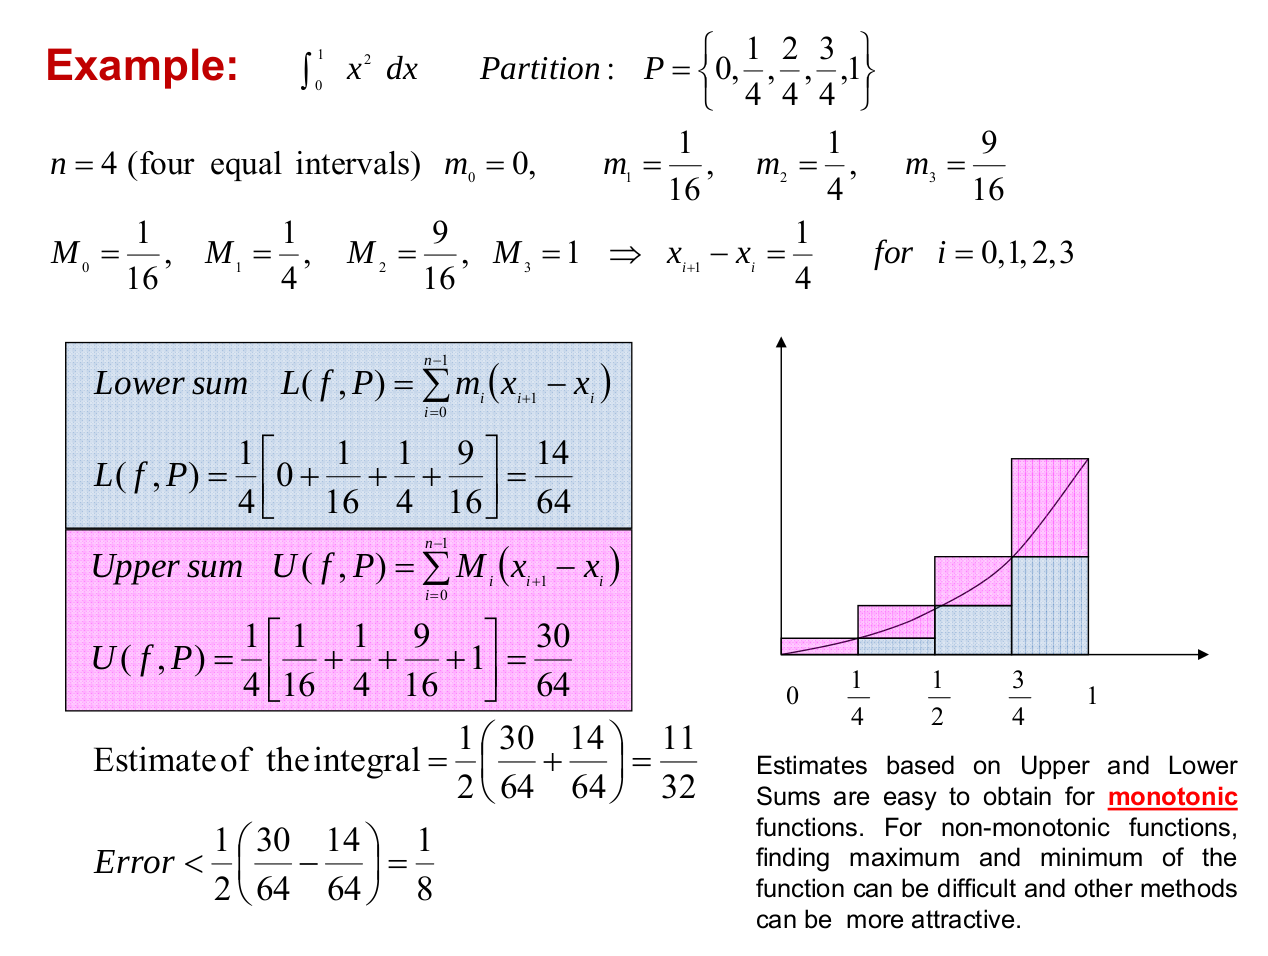

clear;clf;
p = [0 1/4 2/4 3/4 1]

p =          0    0.2500    0.5000    0.7500    1.0000


f = @(x)(x^2);
%Lower sum
n = length(p);
sumary = 0;
for i=1:n-1;
    %delta*high
    sumary = sumary + (p(i+1)-p(i))*f(p(i));
end
disp('Lower sum')

Lower sum


sumary

sumary = 0.2188


LowerSum(f,p);

Lower sum is 0.21875




%Uper sum
n = length(p);
sumary = 0;
for i=1:n-1;
    %delta*high
    sumary = sumary + (p(i+1)-p(i))*f(p(i+1));
end
disp('Uper sum')

Uper sum


sumary

sumary = 0.4688


UpperSum(f,p);

Upper sum is 0.46875


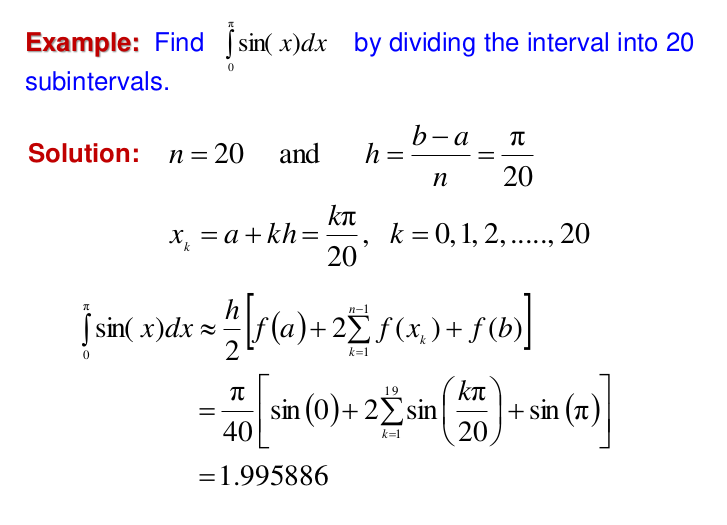

f = @(x)(sin(x))

f = function_handle with value:
    @(x)(sin(x))


TrapComp(f,0,pi,20)

ans = 1.9959

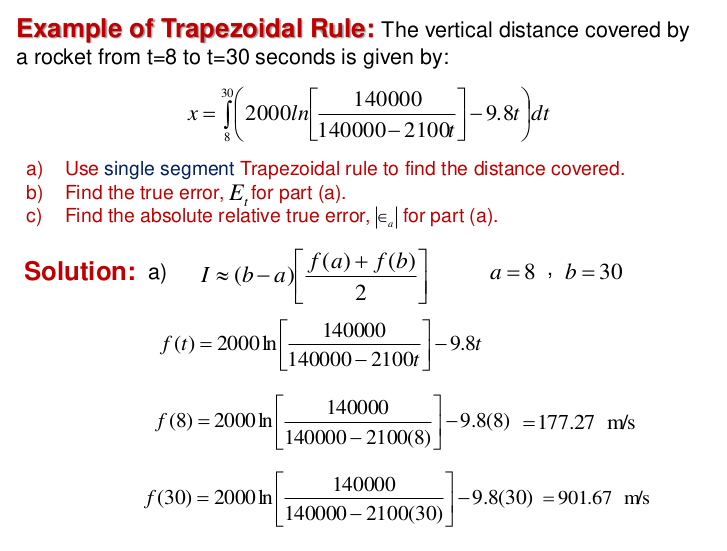

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
disp('a) Trap comp')

a) Trap comp


Sim_var = TrapComp(f,8,30,1)

y =     0.1278    0.5978


y =   177.2667  901.6740


Trap_var = 1.1868e+04


disp('b) ')

b) 


disp('integral')

integral


t_var = integral(f,8,30)

y =     0.1278    0.1278    0.1279    0.1280    0.1283    0.1288    0.1296    0.1306    0.1318    0.1331    0.1346    0.1359    0.1370    0.1379    0.1383    0.1385    0.1389    0.1398    0.1412    0.1430    0.1453    0.1479    0.1509    0.1540    0.1572    0.1602    0.1629    0.1651    0.1667    0.1675    0.1678    0.1686    0.1702    0.1726    0.1757    0.1794    0.1836    0.1882    0.1929    0.1976    0.2019    0.2058    0.2089    0.2110    0.2121    0.2125    0.2136    0.2158    0.2190    0.2232


t_var = 1.1061e+04

E = t_var - Sim_var

E = -807.0127


disp('c) ')

c) 


abs(E/t_var*100)

ans = 7.2958

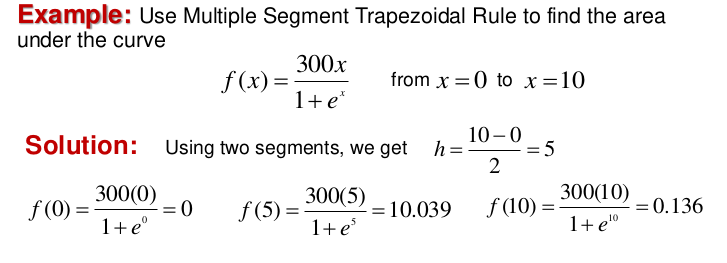

clear;clf;clc 
f = @(x)((300*x)./(1+exp(x)));
f(5)

ans = 10.0393

TrapComp(f,0,10,1000)

y =          0    1.4925    2.9700    4.4325    5.8800    7.3125    8.7301   10.1326   11.5203   12.8929   14.2506   15.5934   16.9213   18.2343   19.5324   20.8157   22.0841   23.3377   24.5765   25.8006   27.0100   28.2046   29.3846   30.5499   31.7006   32.8368   33.9584   35.0655   36.1581   37.2363   38.3002   39.3497   40.3849   41.4058   42.4126   43.4052   44.3836   45.3481   46.2985   47.2349   48.1575   49.0662   49.9611   50.8423   51.7098   52.5637   53.4040   54.2309   55.0443   55.8444


ans = 246.5890

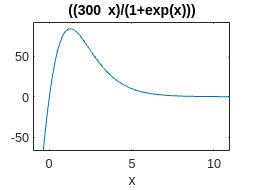

ezplot(f,[-1 11])

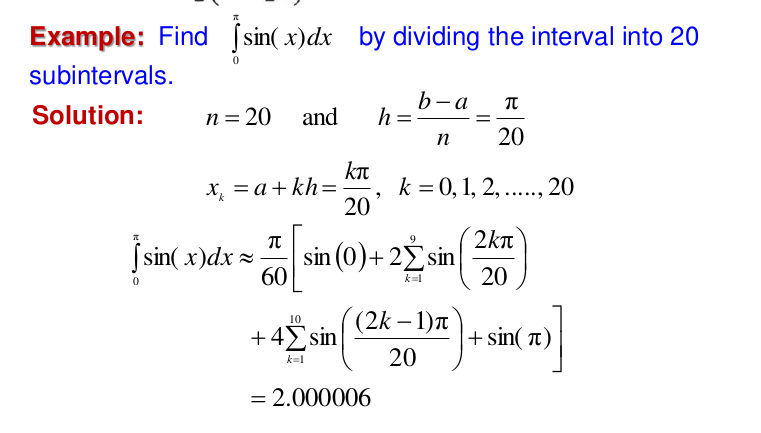

clear;clf;
f = @(x)(sin(x))

f = function_handle with value:
    @(x)(sin(x))


Simpson(f,0,pi,20)

ans = 2.0000

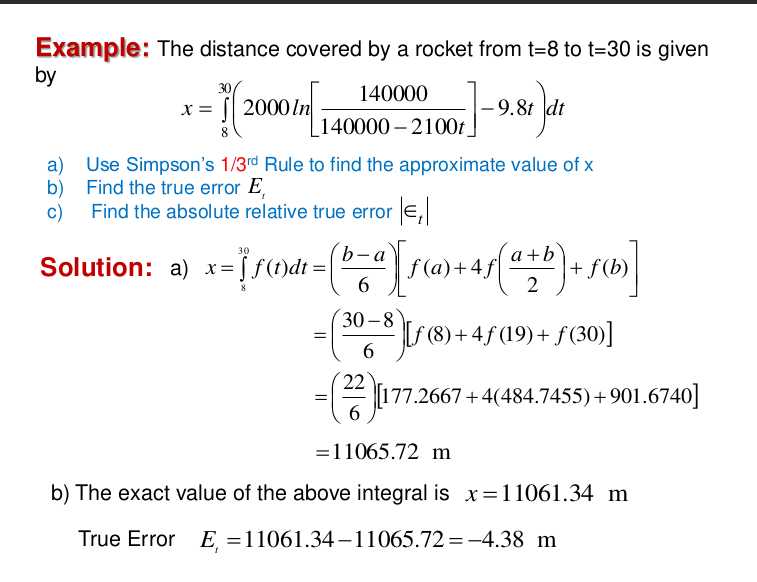

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
disp('a) Trap comp')

a) Trap comp


Sim_var = Simpson(f,8,30,4)

y = 0.1278

y = 0.2263

y = 0.3355

y = 0.3355

y = 0.4581

y = 0.5978

Sim_var = 1.1062e+04


disp('b) ')

b) 


disp('integral')

integral


t_var = integral(f,8,30)

y =     0.1278    0.1278    0.1279    0.1280    0.1283    0.1288    0.1296    0.1306    0.1318    0.1331    0.1346    0.1359    0.1370    0.1379    0.1383    0.1385    0.1389    0.1398    0.1412    0.1430    0.1453    0.1479    0.1509    0.1540    0.1572    0.1602    0.1629    0.1651    0.1667    0.1675    0.1678    0.1686    0.1702    0.1726    0.1757    0.1794    0.1836    0.1882    0.1929    0.1976    0.2019    0.2058    0.2089    0.2110    0.2121    0.2125    0.2136    0.2158    0.2190    0.2232


t_var = 1.1061e+04

E = t_var - Sim_var

E = -0.3006


disp('c) ')

c) 


abs(E/t_var*100)

ans = 0.0027

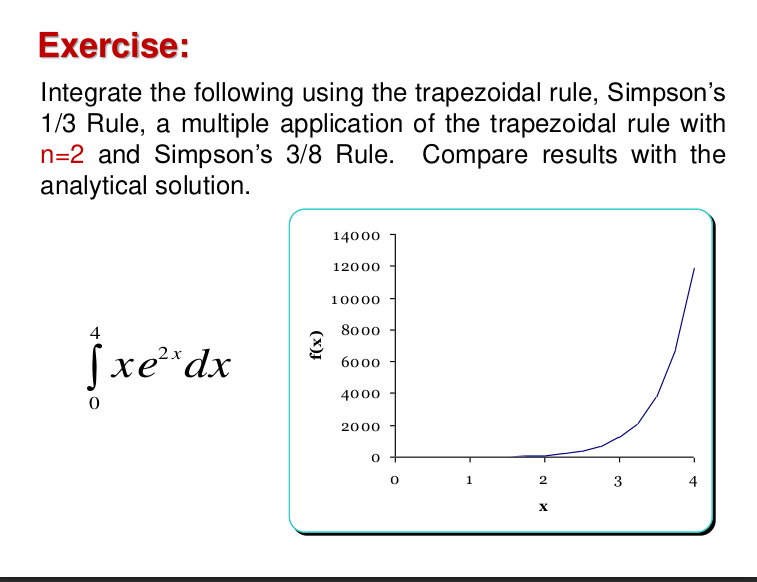

clear;clf;
f = @(x)(x.*exp(2.*x));
disp('integral')

integral


integral(f,0,4)

ans = 5.2169e+03

disp('Simpson')

Simpson


Simpson(f,0,4,2)

ans = 8.2404e+03

disp('TrapComp 1/3')

TrapComp 1/3


TrapComp(f,0,4,2)

ans = 1.2142e+04

disp('TrapComp 3/8')

TrapComp 3/8


disp('Error 404 not found')

Error 404 not found


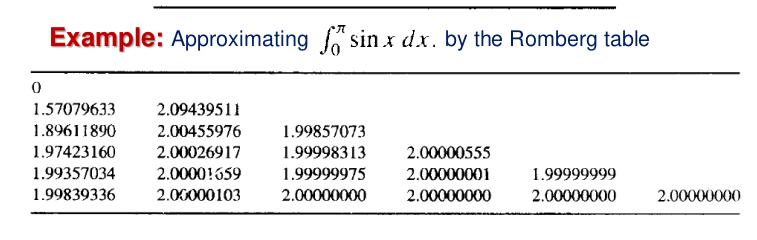

clear;clc;clf;
f = @(x)(sin(x));
Romberg(f,0,pi,pi,6)

ans =     1.8213    1.9907    1.9900    2.0042    1.9996    1.9999
    1.9484    1.9900    2.0040    1.9996    1.9999         0
    1.9796    2.0031    1.9996    1.9999         0         0
    1.9973    1.9999    1.9999         0         0         0
    1.9992    1.9999         0         0         0         0
    1.9997         0         0         0         0         0


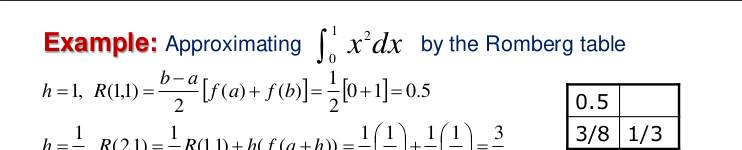

clear;clc;clf;
f = @(x)(x.^2);
Romberg(f,0,1,1,3)

ans =     0.5000    0.3333    0.3333
    0.3750    0.3333         0
    0.3438         0         0


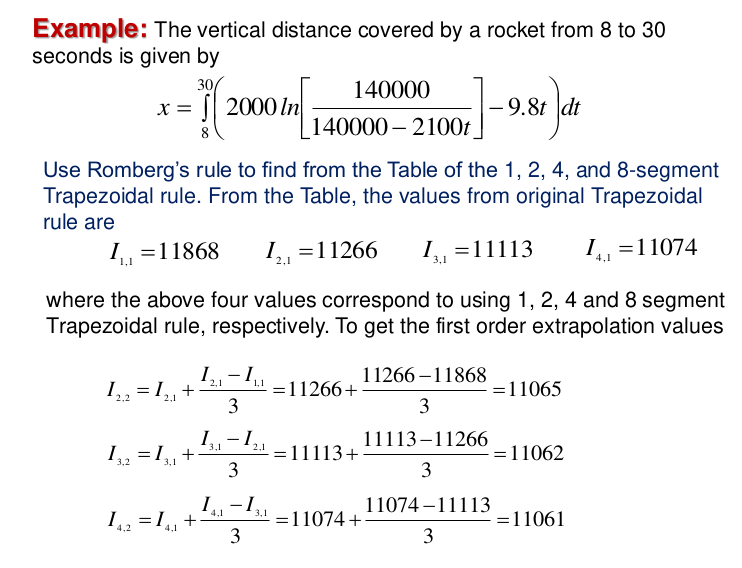

clear;clf;
f = @(t)(2000.*ln(14e4./(14e4-2100.*t))-9.8.*t);
Romberg(f,8,30,30,5)

y =     0.1278    0.1404    0.1532    0.1661    0.1791    0.1924    0.2058    0.2194    0.2332    0.2472    0.2614    0.2758    0.2904    0.3052    0.3202    0.3355    0.3510    0.3667    0.3827    0.3990    0.4155    0.4323    0.4494    0.4668    0.4845    0.5025    0.5209    0.5396    0.5586    0.5780    0.5978


y =     0.1278    0.1341    0.1404    0.1468    0.1532    0.1596    0.1661    0.1726    0.1791    0.1857    0.1924    0.1991    0.2058    0.2126    0.2194    0.2263    0.2332    0.2402    0.2472    0.2542    0.2614    0.2685    0.2758    0.2830    0.2904    0.2977    0.3052    0.3127    0.3202    0.3278    0.3355    0.3432    0.3510    0.3588    0.3667    0.3747    0.3827    0.3908    0.3990    0.4072    0.4155    0.4239    0.4323    0.4408    0.4494    0.4581    0.4668    0.4756    0.4845    0.4935


y =     0.1278    0.1310    0.1341    0.1373    0.1404    0.1436    0.1468    0.1500    0.1532    0.1564    0.1596    0.1628    0.1661    0.1693    0.1726    0.1758    0.1791    0.1824    0.1857    0.1890    0.1924    0.1957    0.1991    0.2024    0.2058    0.2092    0.2126    0.2160    0.2194    0.2228    0.2263    0.2297    0.2332    0.2367    0.2402    0.2437    0.2472    0.2507    0.2542    0.2578    0.2614    0.2649    0.2685    0.2721    0.2758    0.2794    0.2830    0.2867    0.2904    0.2940


y =     0.1278    0.1294    0.1310    0.1325    0.1341    0.1357    0.1373    0.1388    0.1404    0.1420    0.1436    0.1452    0.1468    0.1484    0.1500    0.1515    0.1532    0.1548    0.1564    0.1580    0.1596    0.1612    0.1628    0.1644    0.1661    0.1677    0.1693    0.1709    0.1726    0.1742    0.1758    0.1775    0.1791    0.1808    0.1824    0.1841    0.1857    0.1874    0.1890    0.1907    0.1924    0.1940    0.1957    0.1974    0.1991    0.2007    0.2024    0.2041    0.2058    0.2075


y =     0.1278    0.1286    0.1294    0.1302    0.1310    0.1317    0.1325    0.1333    0.1341    0.1349    0.1357    0.1365    0.1373    0.1380    0.1388    0.1396    0.1404    0.1412    0.1420    0.1428    0.1436    0.1444    0.1452    0.1460    0.1468    0.1476    0.1484    0.1492    0.1500    0.1508    0.1515    0.1524    0.1532    0.1540    0.1548    0.1556    0.1564    0.1572    0.1580    0.1588    0.1596    0.1604    0.1612    0.1620    0.1628    0.1636    0.1644    0.1652    0.1661    0.1669


ans = 1.0e+04 *

    1.1062    1.1061    1.1061    1.1061    1.1061
    1.1062    1.1061    1.1061    1.1061         0
    1.1061    1.1061    1.1061         0         0
    1.1061    1.1061         0         0         0
    1.1061         0         0         0         0


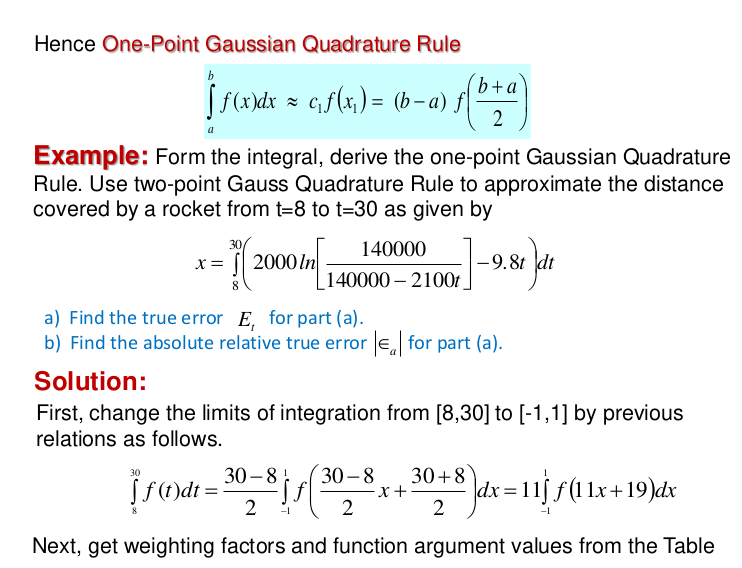

clear;clf;
f = @(x)(2000.*ln(14e4./(14e4-2100.*x))-9.8.*x);
a = 8;
b = 30;
c1 = 1;
c2 = 1

c2 = 1

x1 = -0.577350269;
x2 = 0.577350269;

(b-a)/2*(c1*f(11*x1+19)+c2*f(11*x2+19))

y = 0.2104

y = 0.4785

ans = 1.1058e+04

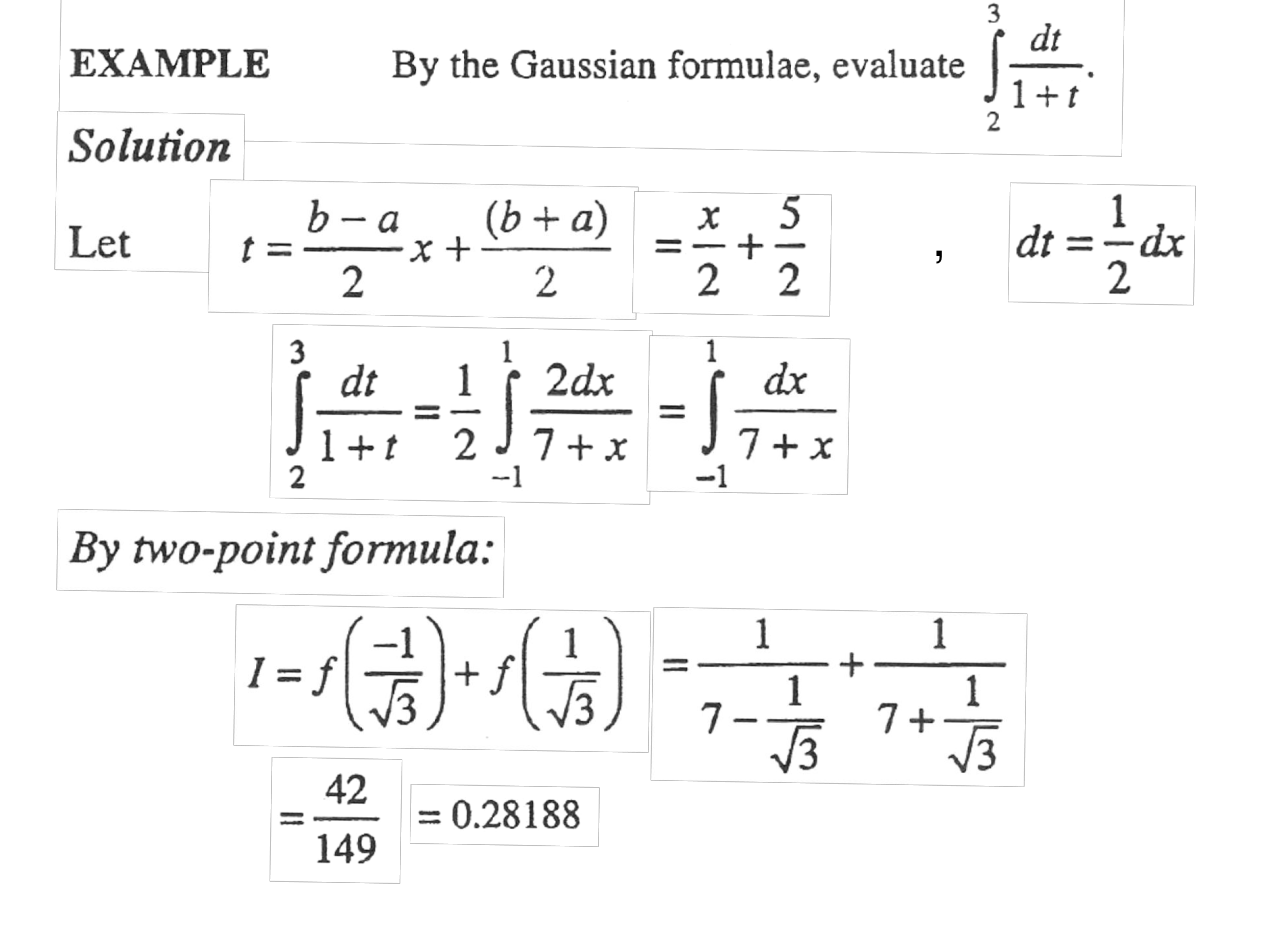

clear;clf;clf;
f = @(x)(1./(1+x));

GaussInt(f,2,3,2)

ans = -0.2877

integral(f,2,3)

ans = 0.2877

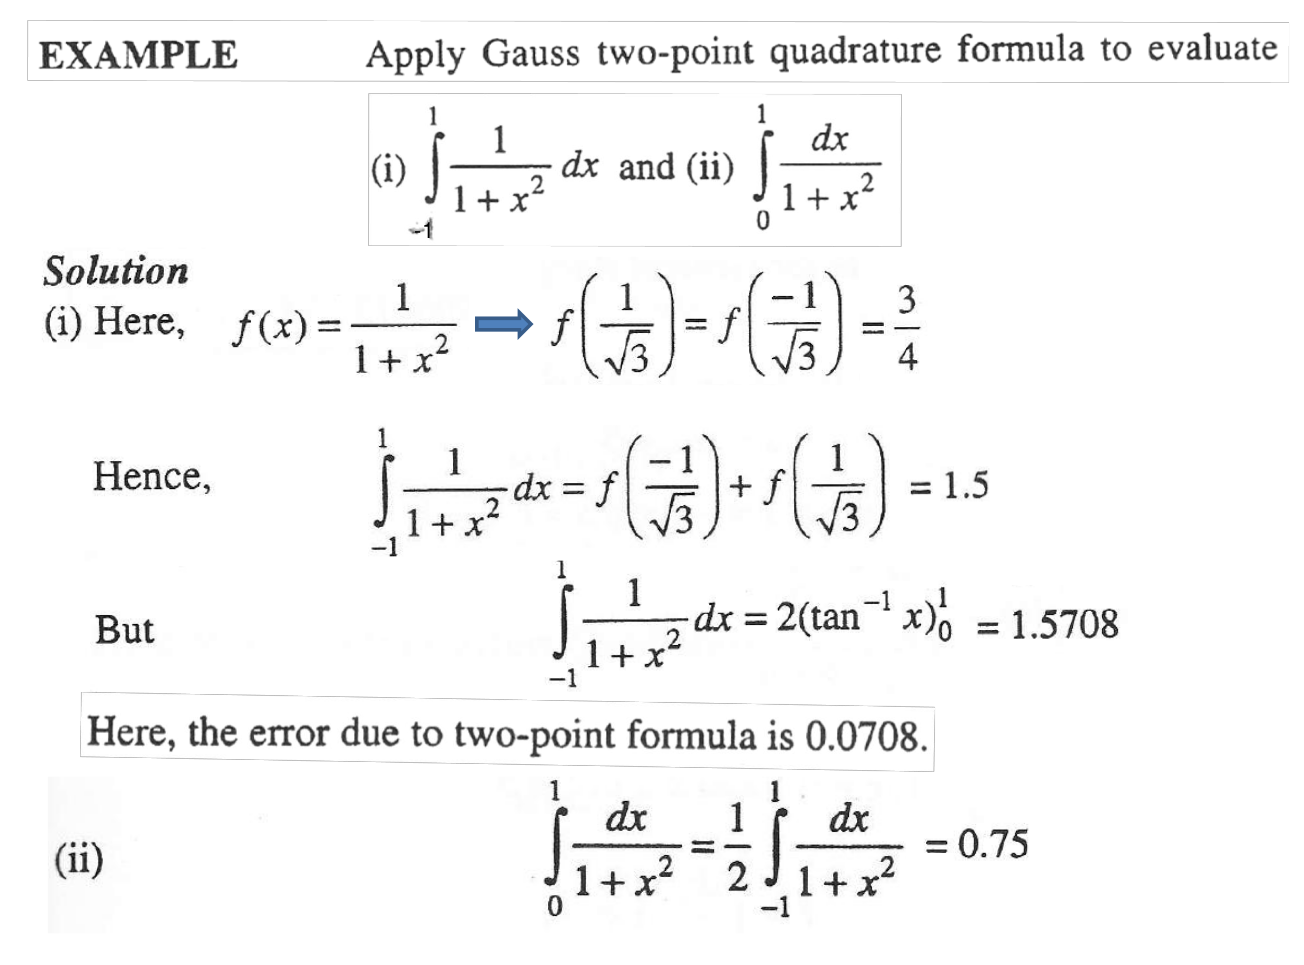

clear;clf;
f = @(x)(1./(1+x.^2))

f = function_handle with value:
    @(x)(1./(1+x.^2))


GaussInt(f,-1,1,2)

ans = 1.5000

GaussInt(f,-1,1,6)

ans = 1.5707


GaussInt(f,0,1,2)

ans = 0.7869

GaussInt(f,0,1,6)

ans = 0.7854

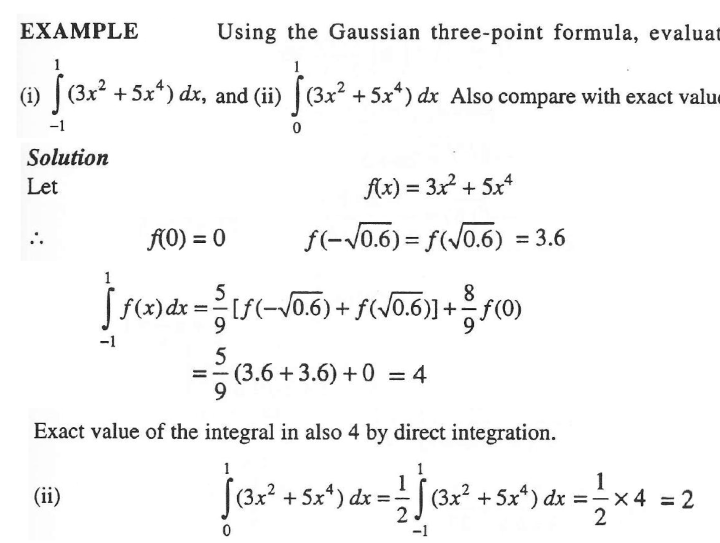

clear;clf;
f = @(x)(3.*x.^2+5.*x.^4)

f = function_handle with value:
    @(x)(3.*x.^2+5.*x.^4)


GaussInt(f,-1,1,3)

ans = 4.0000



GaussInt(f,0,1,3)

ans = 2.0000

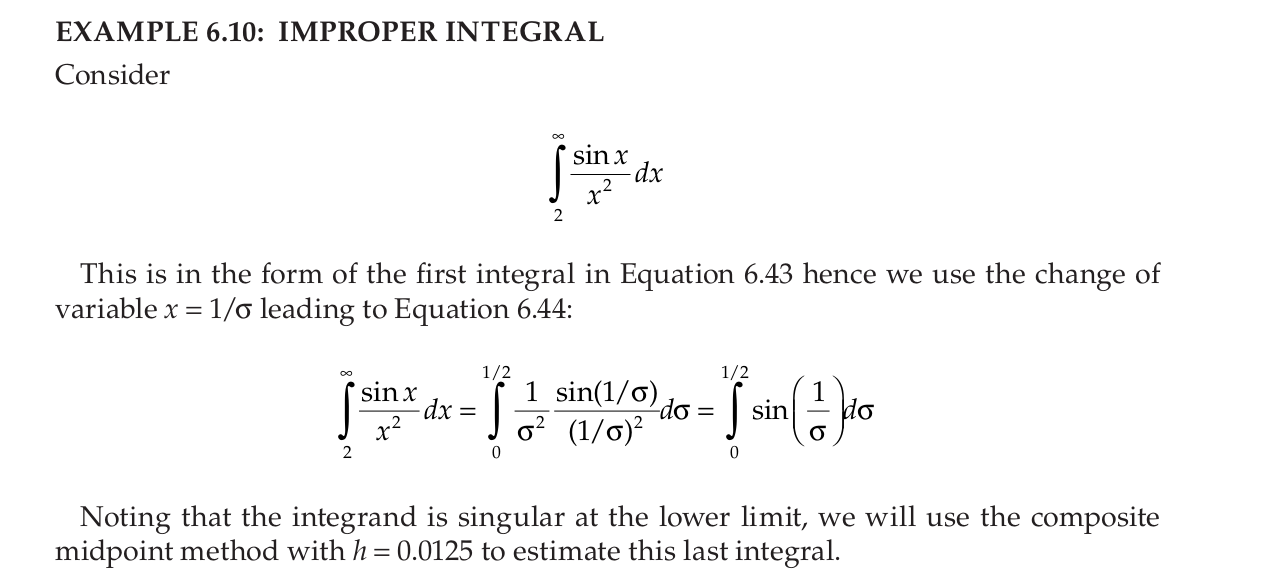

clear;clf;clf;
% Use s to represent sigma
f = @(s)(sin(1/s)); 
h = 0.0125; 
s = 0:h:0.5;

n = length(s)-1; 
m = zeros(n,1); 

I = 0;
for i = 1:n,
    m(i) = (s(i+1)+s(i))/2;
    I = I + f(m(i));
end
I = I*h

I = 0.0277